# Time Domain Optimization - Free Decay

## Define all shared variables

clc; clear;

% Run Read_AQWA and process_hydro
hydro = struct();
hydro = Read_AQWA2(hydro,'BEMData/FullScale/ANALYSIS.ah1','BEMData/FullScale/ANALYSIS.lis');

rng('default')
% Wave Data 
T_wave = 5;
f_wave = 1/T_wave;
w_wave = f_wave*(2*pi);
w_delta = 0.01;
w_spectrum = 0.1:w_delta:2;
w_BEM = hydro.w;
h_wave = 1.5;
t_ramp = T_wave*0;
phase = 2*pi*rand(length(w_spectrum),1)';
BEM = process_hydro(hydro,T_wave);

% WaveData struct for regular waves 
waveData = struct();

waveData.h_wave = h_wave;
waveData.w_wave = w_wave;
waveData.t_ramp = t_ramp;

% Mass ratio
mu = 0.03;

m1 = body.m1;
m = (m1*mu)/3;

body.m = m;

% Length of simulation
fs = 10;
duration = 800;
N = fs*duration;
t = 0:1/fs:duration;

## Define irregular wave specific variables

F11_vector_re = BEM.F11_vector_re;     
F11_vector_im = BEM.F11_vector_im; 
F33_vector_re = BEM.F33_vector_re;     
F33_vector_im = BEM.F33_vector_im;     
F55_vector_re = BEM.F55_vector_re;     
F55_vector_im = BEM.F55_vector_im; 

Fex_irreg_fun = @(t) excitation_force_irregular_3DOF(t,w_wave,h_wave,w_spectrum,w_delta,w_BEM,phase,F11_vector_re,F11_vector_im,F33_vector_re,F33_vector_im,F55_vector_re,F55_vector_im);

## Set up optimization

k_lb = 210000; k_ub = 240000;
c_lb = 1; c_ub = 5000;
c_lb_i = 1; c_ub_i = 3000;
k_i_lb = 10; k_i_ub = 3000;
b_lb = 10; b_ub = 3000;

lb_TMD = [k_lb,c_lb];
ub_TMD = [k_ub,c_ub];

lb_TID = [k_lb,c_lb_i,k_i_lb,b_lb];
ub_TID = [k_ub,c_ub_i,k_i_ub,b_ub];

## Set up initial conditions - heave

r0_noPTO = [0 0 deg2rad(0)];
v0_noPTO = [0 0 0];
y0_noPTO = [r0_noPTO v0_noPTO];

r0_TMD = [0 0 deg2rad(0) body.L2_0 body.L3_0 body.L4_0];
v0_TMD = [0 0 0 0 0 0];
y0_TMD = [r0_TMD v0_TMD];

r0_TID = [0 0 deg2rad(0) body.L2_0 body.L3_0 body.L4_0 body.L5_0 body.L6_0 body.L7_0];
v0_TID = [0 0 0 0 0 0 0 0 0];
y0_TID = [r0_TID v0_TID];

## Run optimization - heave



Iter     Func-count       f(x)      MeshSize     Method
    0           1      0.0135145             1      
    1           3      0.0135139             2     Successful Poll
    2           5      0.0135128             4     Successful Poll
    3           7      0.0135111             8     Successful Poll
    4           8      0.0135111             4     Refine Mesh
    5          10      0.0135111             2     Refine Mesh
    6          12      0.0135108             4     Successful Poll
    7          13      0.0135108             2     Refine Mesh
    8          15      0.0135108             1     Refine Mesh
    9          17      0.0135108           0.5     Refine Mesh
   10          19      0.0135108          0.25     Refine Mesh
   11          21      0.0135108         0.125     Refine Mesh
   12          23      0.0135108          0.25     Successful Poll
   13          25      0.0135108         0.125     Refine Mesh
   14          27      0.0135108        0.0625    

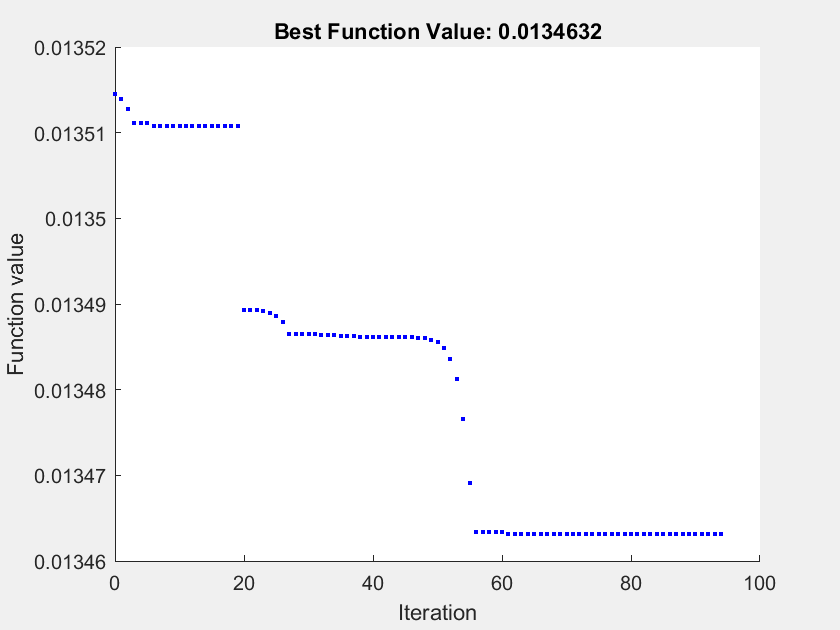

options_p = optimoptions('patternsearch','Display','iter','PlotFcn',@psplotbestf,'MeshTolerance',1e-3,'MaxIterations',2400,'Cache','off');
options_f = optimoptions('fmincon','Display','iter','PlotFcn','optimplotx','OptimalityTolerance',1e-7);

f_TMD = @(tmd) objfun_TD_IRREG(t,body,BEM,y0_TMD,tmd,'TMD','both',waveData,Fex_irreg_fun);
[tmd_opt, fval_TMD] = patternsearch(f_TMD,tmd_TMD_reg_SS1,[],[],[],[],lb_TMD,ub_TMD,[],options_p);



Iter     Func-count       f(x)      MeshSize     Method
    0           1      0.0135617             1      
    1           2      0.0135604             2     Successful Poll
    2           3       0.013559             4     Successful Poll
    3           4      0.0135583             8     Successful Poll
    4           6       0.013541            16     Successful Poll
    5           7      0.0135103            32     Successful Poll
    6           7      0.0135103            16     Refine Mesh
    7           8      0.0134851            32     Successful Poll
    8           8      0.0134851            16     Refine Mesh
    9          10      0.0134851             8     Refine Mesh
   10          11       0.013484            16     Successful Poll
   11          13       0.013484             8     Refine Mesh
   12          17       0.013484             4     Refine Mesh
   13          18      0.0134836             8     Successful Poll
   14          22      0.0134836      

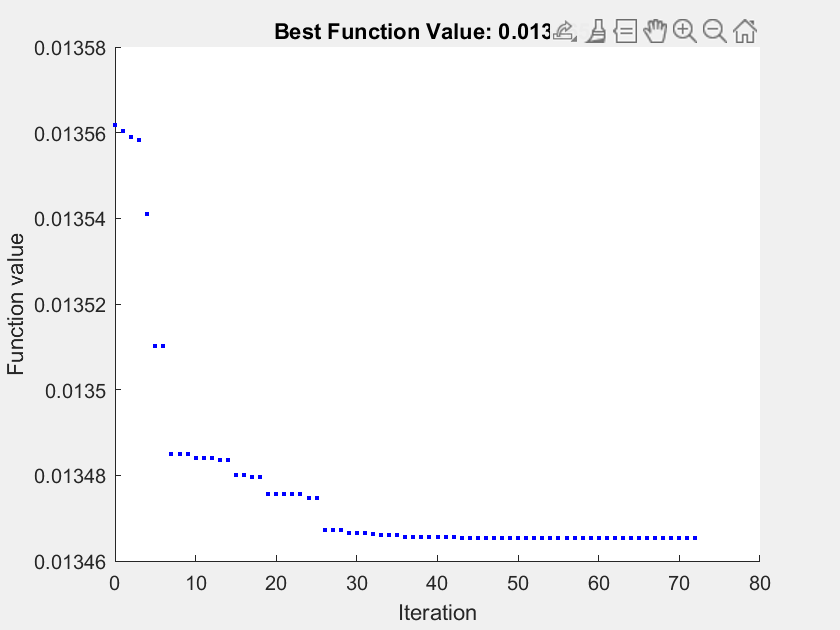


f_TID = @(tmd) objfun_TD_IRREG(t,body,BEM,y0_TID,tmd,'TID','both',waveData,Fex_irreg_fun);
[tid_opt, fval_TID] = patternsearch(f_TID,tmd_TID_reg_SS1,[],[],[],[],lb_TID,ub_TID,[],options_p);

## Run studies - heave

fs = 20;
duration = 5000;
N = fs*duration;
t = 0:1/fs:duration;

[t, x_noPTO_irreg] = run_dynamic_study(t,body,BEM,y0_noPTO,'PTO','No PTO','waveType','Irregular','waveData',waveData,'Fex_irreg_fun',Fex_irreg_fun);
[t, x_tmd_irreg] = run_dynamic_study(t,body,BEM,y0_TMD,tmd_TMD_reg_SS1,'PTO','TMD','waveType','Irregular','waveData',waveData,'Fex_irreg_fun',Fex_irreg_fun);
[t, x_tid_irreg] = run_dynamic_study(t,body,BEM,y0_TID,tmd_TID_reg_SS1,'PTO','TID','waveType','Irregular','waveData',waveData,'Fex_irreg_fun',Fex_irreg_fun);

## Plot results - time

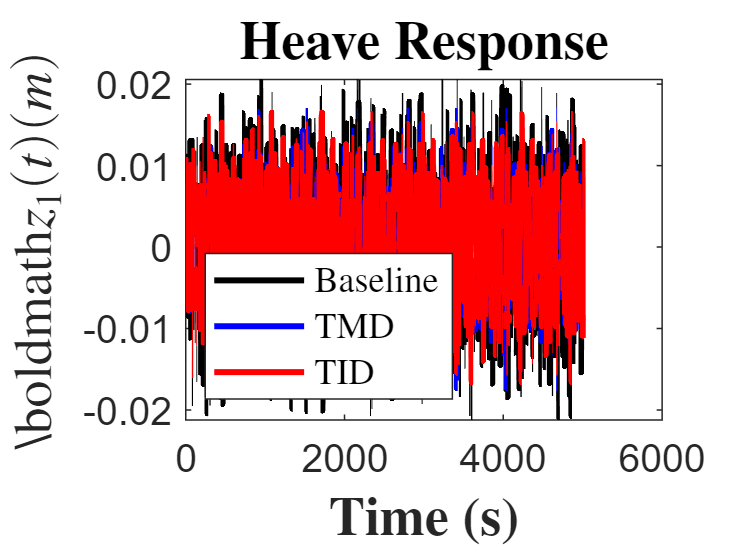

close all;
figure(1)
plot(t,x_noPTO_irreg(:,2),'k','LineWidth',2)
hold on
plot(t,x_tmd_irreg(:,2),'b','LineWidth',2)
plot(t,x_tid_irreg(:,2),'r','LineWidth',2)
yticks([-0.02 -0.01 0 0.01 0.02])
% xlim([0 200])
set(gca,'FontSize',13)
title('\textbf{Heave Response}','Interpreter','latex',"FontSize",18')
xlabel('\textbf{Time (s)}','Interpreter','latex',"FontSize",18)
ylabel('\boldmath$z_{1}(t) (m)$','Interpreter','latex',"FontSize",18)
legend('Baseline', 'TMD','TID','Location','southwest','interpreter', 'latex',"FontSize",12)
hold off

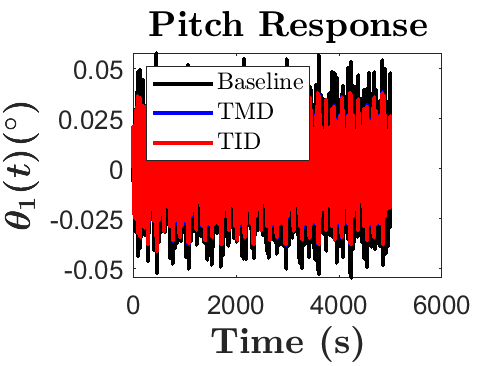


figure(2)
plot(t,x_noPTO_irreg(:,3)*(180/pi),'k','LineWidth',2)
hold on
plot(t,x_tmd_irreg(:,3)*(180/pi),'b','LineWidth',2)
plot(t,x_tid_irreg(:,3)*(180/pi),'r','LineWidth',2)
% xlim([0 200])
yticks([-0.05 -0.025 0 0.025 0.05])
set(gca,'FontSize',13)
title('\textbf{Pitch Response}','Interpreter','latex',"FontSize",18')
xlabel('\textbf{Time (s)}','Interpreter','latex',"FontSize",18)
ylabel('\boldmath$\theta_{1}(t) (^{\circ})$','Interpreter','latex',"FontSize",18)
legend('Baseline', 'TMD','TID','Location','northwest','interpreter', 'latex',"FontSize",12)
hold off

## Fourier transform

warning off;
SS_i = fs*3000;

[f_baseline_heave,S_baseline_heave] = calculate_fourier_transform(x_noPTO_irreg(1000:end,2),fs);
[f_baseline_pitch,S_baseline_pitch] = calculate_fourier_transform(x_noPTO_irreg(1000:end,3),fs);

[f_tmd_heave,S_tmd_heave] = calculate_fourier_transform(x_tmd_irreg(1000:end,2),fs);
[f_tmd_pitch,S_tmd_pitch] = calculate_fourier_transform(x_tmd_irreg(1000:end,3),fs);

[f_tid_heave,S_tid_heave] = calculate_fourier_transform(x_tid_irreg(1000:end,2),fs);
[f_tid_pitch,S_tid_pitch] = calculate_fourier_transform(x_tid_irreg(1000:end,3),fs);
warning on;

## Plot results - frequency

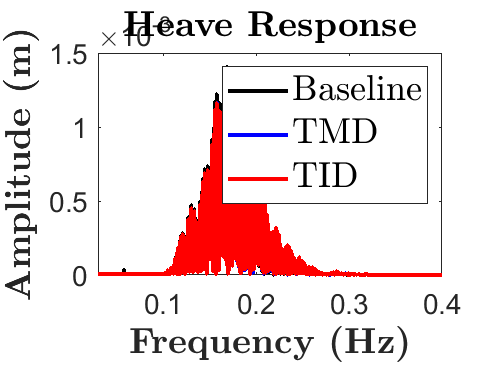

close all;

figure(3)
plot(f_baseline_heave,S_baseline_heave,'Color','k','LineWidth',2)
hold on
plot(f_baseline_heave,S_tmd_heave,'Color','b','LineWidth',2)
plot(f_baseline_heave,S_tid_heave,'Color','r','LineWidth',2)
set(gca,"FontSize",14)
title('\textbf{Heave Response}','Interpreter','latex',"FontSize",18)
xlabel('\textbf{Frequency (Hz)}','Interpreter','latex',"FontSize",18)
ylabel('\textbf{Amplitude (m)}','Interpreter','latex',"FontSize",18)
legend('Baseline','TMD','TID','Location','northeast','Interpreter','latex','FontSize',18)
xlim([0.03 0.4])
% ylim([0 0.05])
hold off

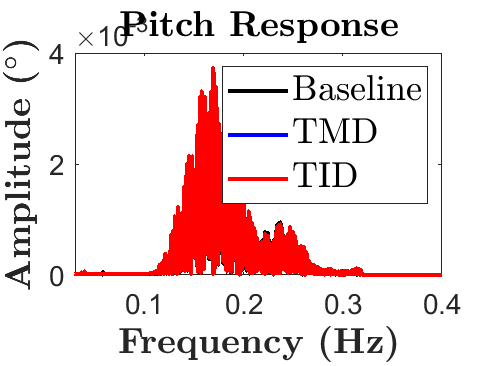


figure(4)
plot(f_baseline_pitch,S_baseline_pitch*(180/pi),'Color','k','LineWidth',2)
hold on
plot(f_baseline_pitch,S_tmd_pitch*(180/pi),'Color','b','LineWidth',2)
plot(f_baseline_pitch,S_tid_pitch*(180/pi),'Color','r','LineWidth',2)
set(gca,"FontSize",14)
title('\textbf{Pitch Response}','Interpreter','latex',"FontSize",18)
xlabel('\textbf{Frequency (Hz)}','Interpreter','latex',"FontSize",18)
ylabel('\textbf{Amplitude} \boldmath$(^{\circ})$','Interpreter','latex',"FontSize",18)
legend('Baseline','TMD','TID','Location','northeast','Interpreter','latex','FontSize',18)
xlim([0.03 0.4])
% ylim([0 0.15])
hold off

## Calculate irregular wave spectra

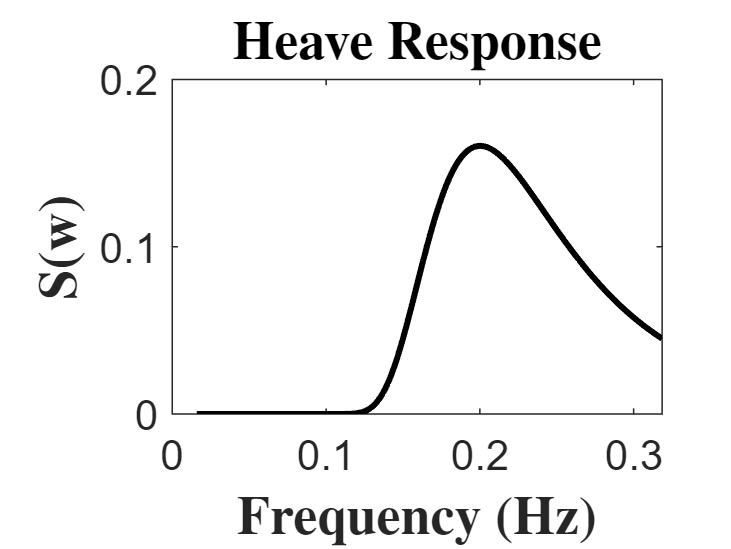

[Sw,Aw] = calculate_irregular_spectra(w_wave,h_wave,w_spectrum,w_delta);

figure(5)
plot(w_spectrum/6.28,Sw,'k-','LineWidth',2)
set(gca,"FontSize",14)
title('\textbf{Heave Response}','Interpreter','latex',"FontSize",18)
xlabel('\textbf{Frequency (Hz)}','Interpreter','latex',"FontSize",18)
ylabel('\textbf{S(w)}','Interpreter','latex',"FontSize",18)